% Clear workspace and command window
clear; clc; close all;

%% 1. Initialize and Load the Network
inp_file = 'Net1.inp'; 
d = epanet(inp_file);

EPANET version {20305} loaded (EMT version {v2.3.5.2 - Last Update: 03/03/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "Net1.inp"...
Input File "Net1.inp" loaded successfully.



%% 2. Configure Water Quality Parameters & Injection Pattern
% Set the water quality analysis type to Chemical
d.setQualityType('CHEM', 'mg/L'); 

% Apply global pipe reaction decay rates
num_links = d.getLinkCount;
d.setLinkBulkReactionCoeff(ones(1, num_links) * -0.5); 
d.setLinkWallReactionCoeff(ones(1, num_links) * -1.0); 

% Define a 24-hour repeating pulse pattern (4 hours ON at 1.5 mg/L, 4 hours OFF)
cyclic_multipliers = [1.5, 1.5, 1.5, 1.5, 0, 0, 0, 0, 1.5, 1.5, 1.5, 1.5, 0, 0, 0, 0, 1.5, 1.5, 1.5, 1.5, 0, 0, 0, 0];
d.addPattern('CYCLIC_INJ', cyclic_multipliers);
pattern_idx = d.getPatternIndex('CYCLIC_INJ');

% Identify candidate source indices (both ID '9' and the absolute top node)
node_ids = d.getNodeNameID;
coords_cell = d.getNodeCoordinates;
[~, top_node_idx] = max(coords_cell{2}); 
id_9_idx = find(strcmp(node_ids, '9'));
source_nodes = unique([top_node_idx, id_9_idx]);

% Assign the pulsing source profile to the designated supply nodes
for idx = source_nodes
    d.setNodeSourceType(idx, 'CONCEN');
    d.setNodeSourcePatternIndex(idx, pattern_idx);
    d.setNodeSourceQuality(idx, 1.0); 
end

%% 3. Execute Complete Hydraulic & Quality Simulation
% Step 1: Compute and lock network hydraulics across the timeline
d.solveCompleteHydraulics;

% Step 2: Open and initialize the background water quality subsystem
d.openQualityAnalysis;
d.initializeQualityAnalysis(1); % 1 saves results to memory buffer

% Step 3: Run step-by-step transport simulation
tleft = 1;
step_index = 1;
time_steps = [];
node_quality_history = [];

while tleft > 0
    % Resolve current time period calculations
    d.runQualityAnalysis;
    
    % Record elapsed time in hours
    total_duration = d.getTimeSimulationDuration;
    time_steps(step_index) = (total_duration - tleft) / 3600;
    
    % Store the active chemical concentrations for map generation
    node_quality_history(:, step_index) = d.getNodeActualQuality;
    
    % Advance the simulation engine by one water quality time step
    tleft = d.stepQualityAnalysisTimeLeft;
    step_index = step_index + 1;
end

% Step 4: Close the water quality solver safely
d.closeQualityAnalysis;
disp('Water quality simulation engine execution complete.');

Water quality simulation engine execution complete.


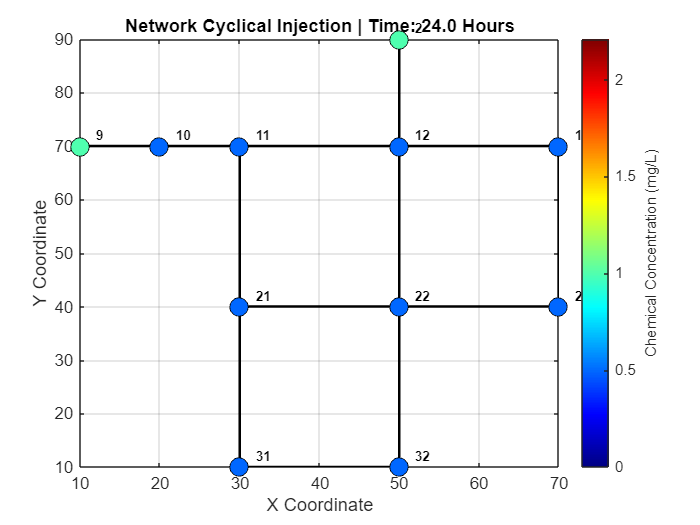

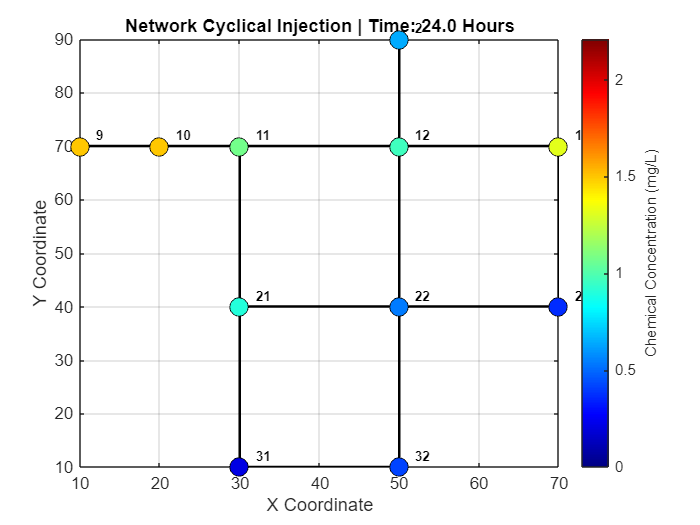


%% 4. Playback Spatial Chemical Wave Animation
x_coords = coords_cell{1}; 
y_coords = coords_cell{2}; 
link_nodes = d.getLinkNodesIndex; 

% Initialize animation figure window
fig = figure('Name', 'Pulsing Water Quality Animation', 'NumberTitle', 'off');

% Establish color bar boundaries based on maximum concentration profile
max_val = max(node_quality_history(:));
if max_val <= 0, max_val = 1.5; end 

% Play through recorded history frames
for t = 1:length(time_steps)
    clf(fig); 
    hold on; grid on; box on;
    
    % Draw pipe framework
    for i = 1:num_links
        from_node = link_nodes(i, 1);
        to_node = link_nodes(i, 2);
        plot([x_coords(from_node), x_coords(to_node)], ...
             [y_coords(from_node), y_coords(to_node)], ...
             'k-', 'LineWidth', 1.5);
    end
    
    % Render nodes color-coded by their active chemical concentration
    spatial_quality = node_quality_history(:, t);
    scatter(x_coords, y_coords, 120, spatial_quality, 'filled', 'MarkerEdgeColor', 'k');
    
    % Apply native standard color scheme
    colormap('jet'); 
    clim([0, max_val]); 
    cb = colorbar;
    ylabel(cb, 'Chemical Concentration (mg/L)');
    
    title(['Network Cyclical Injection | Time: ', num2str(time_steps(t), '%.1f'), ' Hours']);
    xlabel('X Coordinate'); ylabel('Y Coordinate');
    
    % Display Node ID labels
    for i = 1:d.getNodeCount
        text(x_coords(i) + 2, y_coords(i) + 2, node_ids{i}, 'FontSize', 8, 'FontWeight', 'bold');
    end
    
    hold off;
    drawnow;   
    pause(0.15); 
end


%% 5. Unload Toolkit
d.unload;

EPANET Class is unloaded


disp('All visualization sequences finished successfully.');

All visualization sequences finished successfully.
